# Optimisation and Statistical Data Analysis

# Exercise Set 11 Solutions

Set the size of figures.

figure; set(gcf,'position',[0 0 500 300])

## Problem 1

### part a

Enter the data.

t=(1:10)';
y=[-0.083 0.028 0.285 0.780 0.757 1.076 1.173 1.409 1.521 1.773]';

Always look at the data first!

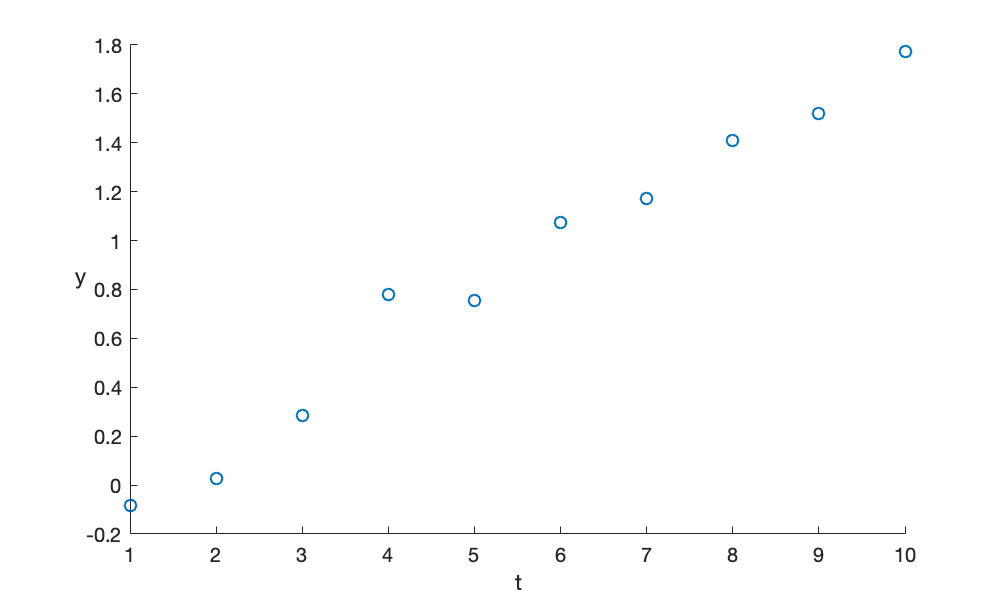

plot(t,y,'o')
xlabel('t'), ylabel('y','rot',0), box off

This plot indicates that it is reasonable to fit a line to this data. 

Compute the posterior distribution's parameters $\hat{\beta}$, $C$, $\hat{\sigma}$ as on slide 14.

n=length(y);
X=[t(:) ones(n,1)];  % design matrix
betahat=X\y          % least squares

betahat =     0.2077
   -0.2705


C=inv(X'*X);         % covariance factor
u=length(betahat);
sigmahat=norm(y-X*betahat)/sqrt(n-u);

The marginal posterior distribution of a parameter is (from slide 13):

$ \beta_i \mid y_{1:n} = \hat{\beta}_i + \hat{\sigma} \sqrt{c_{ii}}\;z, \quad z \sim  \text{t}_{n-2}$. 

The 95% confidence intervals for the parameters:

CI95=tinv(0.975,n-u);   % 95 percent CI of t_{n-u} dist. is [-1,1]*CI95
for i=1:u
    betahat(i) + [-1 1]*sqrt(C(i,i))*sigmahat*CI95
end

ans =     0.1816    0.2338


ans =    -0.4326   -0.1084


### part b

The fitted line (model value) at a given time $\xi$ is (from slide 13):

$\beta_1\xi+\beta_2 \mid y_{1:n}= [ \xi \;1] \beta \mid y_{1:n} = [\xi \;1] \hat{\beta} + \hat{\sigma} \sqrt{[\xi \;1]\,C \,[\xi \;1]^T}z$,    $z \sim  \text{t}_{n-2}$  

Plot the mean and 95% confidence interval of the fitted line: 

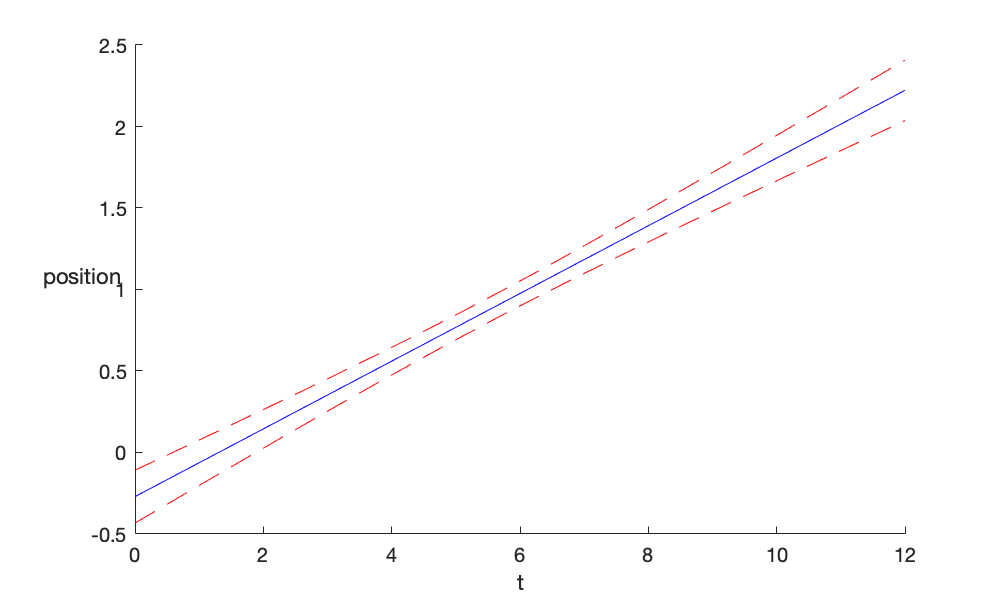

xx=linspace(0,12,20)';      % dense mesh of times
XX=[xx ones(size(xx))];     % design matrix for dense mesh
mvxxmean=XX*betahat;                      % model value mean
mvxxscale=sigmahat*sqrt(diag(XX*C*XX'));  % model value scale
plot(xx,mvxxmean,'b-',...
    xx,mvxxmean+CI95*mvxxscale,'r--',...
    xx,mvxxmean-CI95*mvxxscale,'r--')
box off, xlabel('t'), ylabel('position ','rot',0)

### part c

The posterior predicted measurement at a given $\xi$ is (from slide 15):

$\tilde{y} \mid y_{1:n}= [\xi \;1] \hat{\beta} + \hat{\sigma} \sqrt{1+[\xi \;1]\,C \,[\xi \;1]^T}z$,   $z \sim  \text{t}_{n-2}$  

Plot the mean and 95% CI, together with the actual measurements:

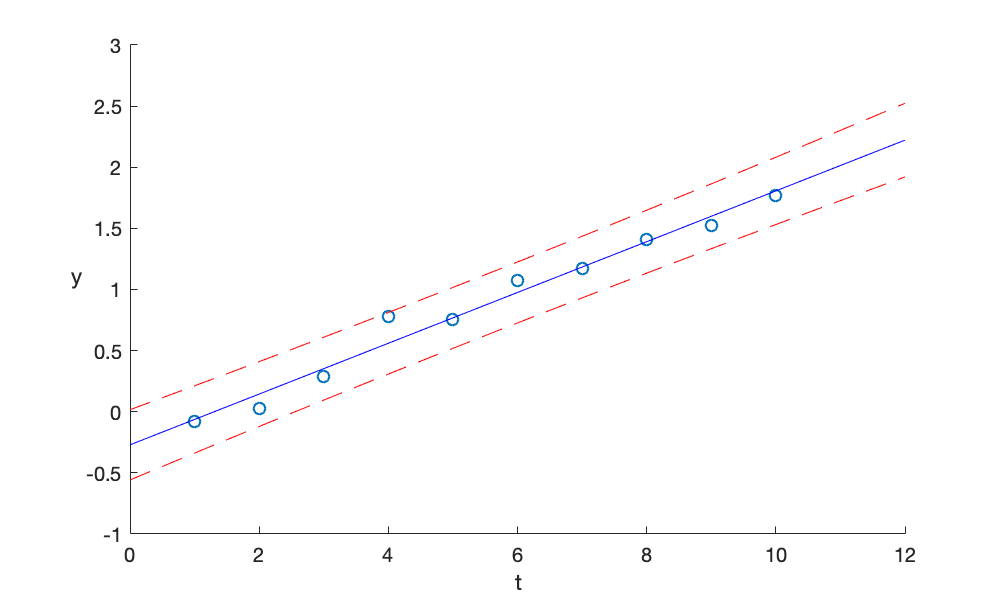

ypredscale=sigmahat*sqrt(1+diag(XX*C*XX')); 
plot(t,y,'o',xx,mvxxmean,'b-',...
    xx,mvxxmean+CI95*ypredscale,'r--',...
    xx,mvxxmean-CI95*ypredscale,'r--')
box off, xlabel('t'), ylabel('y ','rot',0)

The model fit is good: the distribution of observations agrees with the predictive distribution, and there are no evident trends (e.g. curvature) in the sequence of residuals.  

### part d

The scaled residual of observation $y_i$ is (as in slide 15)


$$\frac{y_i -  [x_i \;1]\hat{\beta}}{\hat{\sigma} \sqrt{1+[x_i \;1]\,C \,[x_i \;1]^T}}$$


The QQ plot of scaled residuals vs $\text{t}_{n-2}$ distribution:

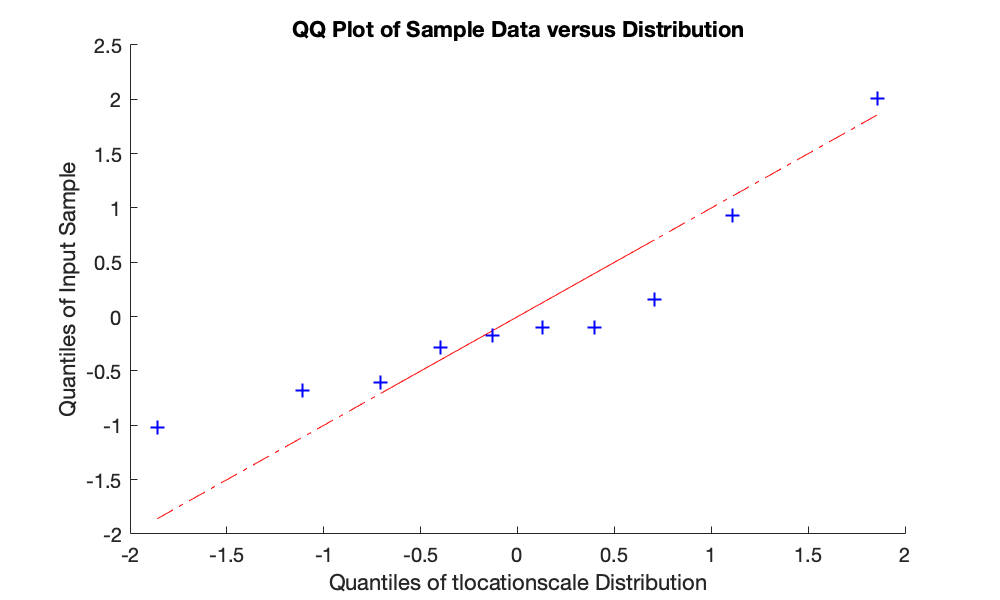

scaledres=(y-X*betahat)./(sigmahat*sqrt(1+diag(X*C*X')));
h=qqplot(scaledres,makedist('tlocationscale','nu',n-u));
h(2).YData=h(2).XData;   % make a 45-degree reference line 
h(3).YData=h(3).XData; 

There's a bit of right-skewness (the points form a "smile") but the fit is reasonably good.

### part e

As in part a, but using the "known" $\sigma$ in place of $\hat{\sigma}$, and the normal distribution in place of Student-t.

Update the parameter distributions one measurement at a time, using the formula on slide 24.

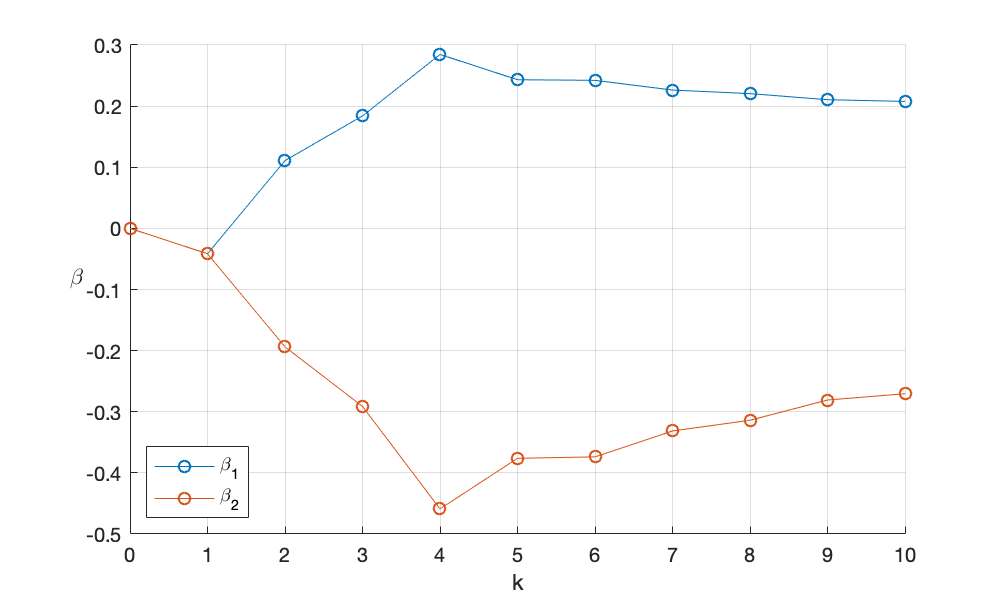

sigma=0.1;               
betahats=nan(u,n);       % preallocate with NaN
b0=[0;0]; P=100*eye(2);  % prior mean and covariance
R=sigma^2;               % measurement noise variance
betahat=b0;
for k=1:n
    H=[t(k) 1];
    S=H*P*H'+R;
    K=P*H'/S;            % backslash is preferable to inv( )
    P=P-K*S*K';
    betahat=betahat+K*(y(k)-H*betahat);
    betahats(:,k)=betahat;
end
plot(0:n,[b0 betahats],'o-')
box off, grid on, xlabel('k'), ylabel('\beta ','rot',0)
legend('\beta_1','\beta_2','location','southwest')

The posterior distribution, given all measurements, is $\beta \mid y_{1:n} \sim \text{MVN}(\hat{\beta}_n,P_n)$ with

betahat, P

betahat =     0.2077
   -0.2705


P =     0.0001   -0.0007
   -0.0007    0.0047


The marginal distributions are $\beta_i \mid y_{1:n} \sim \text{norm}(\hat{\beta}_{n}(i),\sqrt{P_n(i,i)})$. Their 95% confidence intervals are 

CI95=norminv(0.975);   % 95 percent CI of standard normal dist. is [-1,1]*CI95
for i=1:u
    betahat(i) + [-1 1]*sqrt(P(i,i))*CI95
end

ans =     0.1861    0.2293


ans =    -0.4044   -0.1366


## Problem 2

Enter the data and plot it

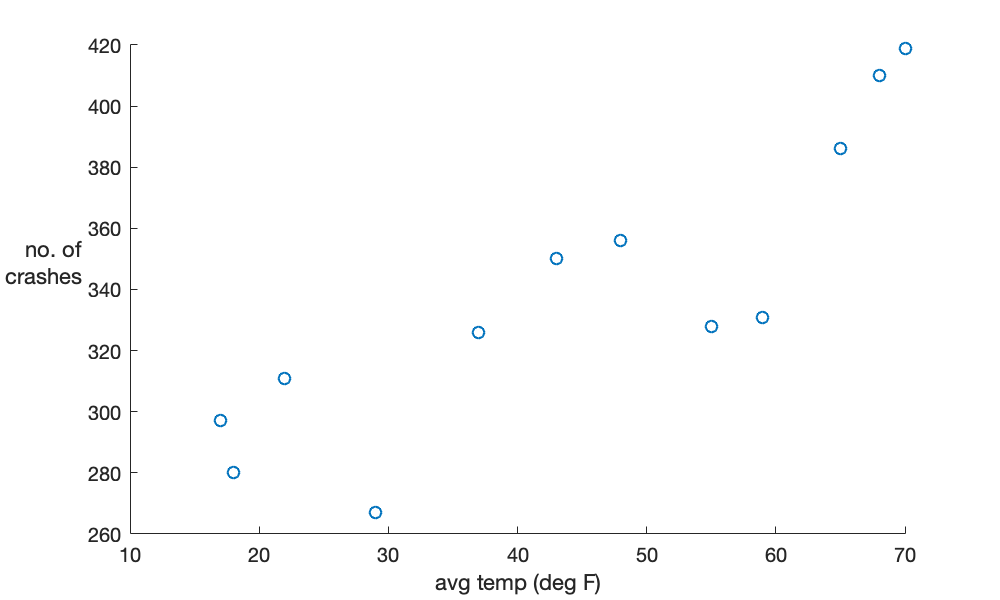

t=[  17  18  29  43  55  65  70  68  59  48  37  22]';
y=[ 297 280 267 350 328 386 419 410 331 356 326 311]';
plot(t,y,'o')
xlabel('avg temp (deg F)'), box off
ylabel({'no. of';'crashes'},'rot',0,'hor','right')

This plot indicates that it is reasonable to fit a line to this data. 

Compute the posterior distribution's parameters $\hat{\beta}$, $C$, $\hat{\sigma}$ as on slide 14.

n=length(y);
X=[t(:) ones(n,1)];  % design matrix
betahat=X\y          % least squares

betahat =     2.1440
  243.5465


C=inv(X'*X);         % covariance factor
u=length(betahat);
sigmahat=norm(y-X*betahat)/sqrt(n-u);

The marginal posterior distribution of the slope parameter is (from slide 13):

$ \beta_1 \mid y_{1:n} = \hat{\beta}_1 + \hat{\sigma} \sqrt{c_{11}}\;z, \quad z \sim  \text{t}_{n-2}$. 

Thus $\text{Prob}(\beta_1 \mid y_{1:12} >  0) = \text{Prob}(z  > -\frac{\hat{\beta}_1}{\hat{\sigma} \sqrt{c_{11}}}\;) = 1- \text{Prob}(z  \leq -\frac{\hat{\beta}_1}{\hat{\sigma} \sqrt{c_{11}}}\;)$ 

format long   % show more digits
Prob=1-tcdf(-betahat(1)/sigmahat/sqrt(C(1,1)),n-2)

Prob =    0.999882490125677


The news headline illustrates a well-known mistake known as the *third-cause fallacy* or *ignoring a common cause. *In this data there are other relevant factors, such as *number of journeys made *and *average speed,* that should be included in a probabilistic model of the number of fatal road accidents on any given day. 